# Minimal Web Server

This example shows how to create a minimal NodeJS web server using the **Interface for Desktop Docker Client** toolbox.

## Create Image

Create a Dockerfile file containing the description of your app. A minimal JavaScript code, `my-web-server.js`, of your app is given as follows.

Add a package.json file to list the necessary packages use by the JavaScript application. For more information on NPM packages, see [package.json](https://docs.npmjs.com/cli/v6/configuring-npm/package-json).

Create the Dockerfile, `Dockerfile`, as textfile with no extension.

Create the image using the following code in the MATLAB command line. This docker image, built on a Node base image, automatically fetches the required packages listed in the `package.json` file.

docker.build("./doc","tag","my_web_server_image:latest")

Sending build context to Docker daemon  164.9kB
Step 1/7 : FROM node:14
 ---> 995ff80c793e
Step 2/7 : WORKDIR /usr/src/app
 ---> Running in 1ab24e981cf2
Removing intermediate container 1ab24e981cf2
 ---> 36e56c383263
Step 3/7 : COPY package*.json ./
 ---> 23271c0ca6c9
Step 4/7 : RUN npm install
 ---> Running in e907a7ed9e20
npm WARN my_web_server@1.0.0 No repository field.
npm WARN my_web_server@1.0.0 No license field.

added 50 packages from 37 contributors and audited 50 packages in 1s
found 0 vulnerabilities

Removing intermediate container e907a7ed9e20
 ---> 5dc162454845
Step 5/7 : COPY . .
 ---> b28dcbcf12c7
Step 6/7 : EXPOSE 8080
 ---> Running in e537814bc358
Removing intermediate container e537814bc358
 ---> 8aac1b8f1631
Step 7/7 : CMD [ "node", "my-web-server.js" ]
 ---> Running in c41d213470a0
Removing intermediate container c41d213470a0
 ---> 7e01c9a86467
Successfully built 7e01c9a86467
Successfully tagged my_web_server_image:latest
SECURITY WARNING: You 

If you open the Docker desktop application, you can see your new image listed.

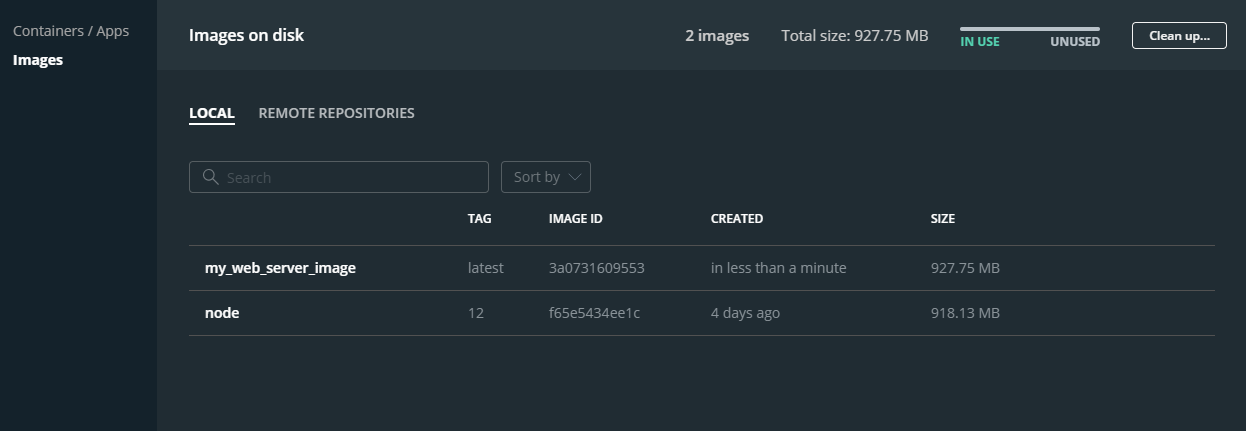

## Create and Launch Container

With the image created on your system, you can now create and launch a container that contains the web server service. To create and launch the container, use th following code in the MATLAB command line. When the container is created

docker.run("my_web_server_image:latest",string.empty(),string.empty(),...
    "name","my_web_server",...
    "publish","31415:8080",...
    "detach",true);

If you open the Docker desktop application, you can see your new container running.

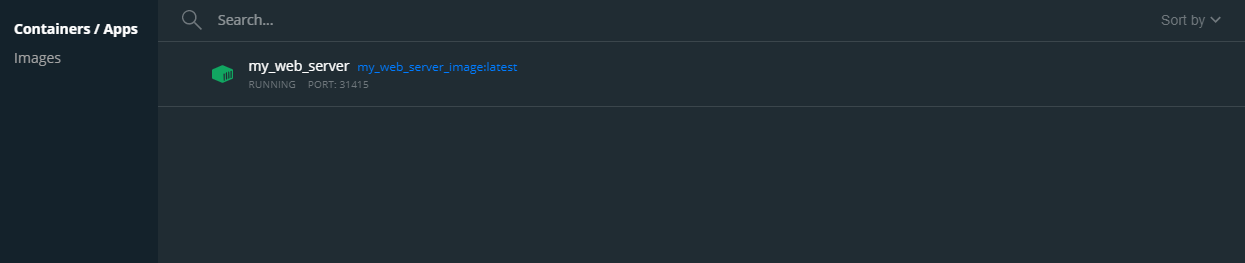

## Ping Web Server in Container

Using the [webread](https://www.mathworks.com/help/matlab/ref/webread.html) function, you can now request data from the running server.

webread("http://localhost:31415")

ans = 'Hello World!'

## Stop and Cleanup Container and Image

When you are done, you can stop and remove the container.

docker.kill("my_web_server");
docker.rm("my_web_server","force",true);

You can also remove the image.

docker.rmi("my_web_server_image:latest");

*Copyright 2021 The MathWorks, Inc.*